# Greenhouse Gases as an explantion for Snowball Earth

*Authors:* Amit Kumar, Tyler Ewald

## Modeling Question:

Can drastic changes in greenhouse gases explain a possible cause for a "snowball earth" scenario? This is an explanatory question that dives into the interesting research surrounding the feasibility and possible causes for how the entire earth was covered in ice. This topic is important to explore as many scientists believe that this event helped lead to the Cambrian explosion and the diversification of life. By modeling this scenario, we will generate a better understanding of energy flows, along with exploring how external factors affect the rates of energy absorption and loss. 

## The Model:

We aimed to answer this question by constructing an energy balance model that tracks the internal energy of the Earth as a single, average value. 

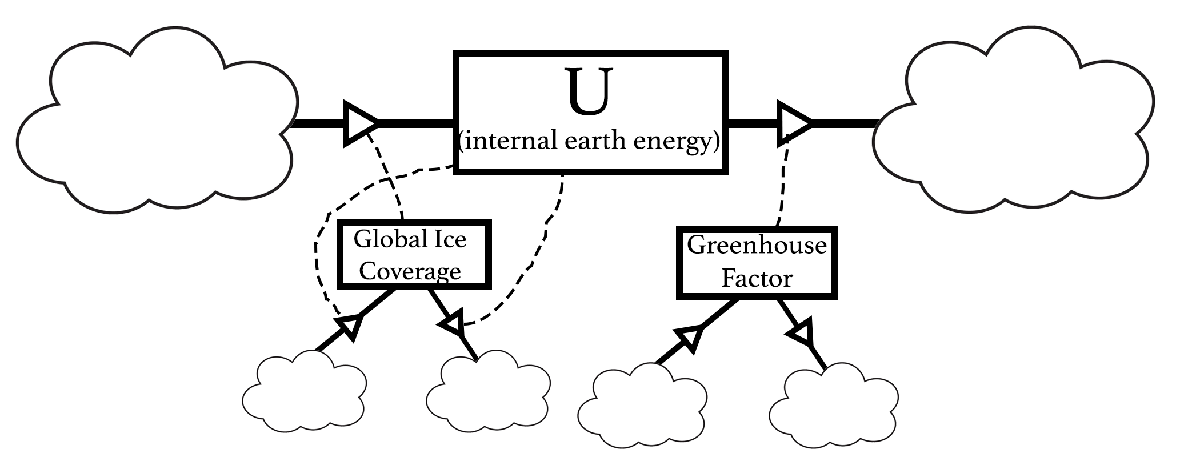

The parameters that are used in our model are:

- S - Energy Flux Density (Energy flowing through 1 $m^2$ ($W/m^2$))

- $\sigma
$ - Stefan-Boltzmann Constant (Used to calculate black-body radiation)

- $\epsilon$ - Greenhouse factor (Portion of outgoing energy that is able to escape the atmosphere and is not trapped by greenhouse gases)

- $\alpha$ - Albedo (Reflectivity - portion of incoming energy that is reflected back out and not absorbed)

Their initial values in our model are as follows

- S = 1367.6 (constant)

- $\sigma
$ = $5\ldotp 67*{10}^{-8}$ (constant)

- $\epsilon = 
$ .6011 (given by findGreenhouseEffect; calculated to be the equilibrium greenhouse effect at 288K)

- $\alpha =$ .3142 (given by findAlbedo; calculations given in following section)

### Assumptions & Abstractions:

- The Earth is symmetrical about the equator

- The Earth radiates energy as a single, homogeneous body

- We assume that there is a linear relationship between albedo and ice coverage

- The Earth is always at a constant temperature, independent from seasonal change

- Representing greenhouse as a factor not affected by temperature

Our first 3 iterations were meant to familiarize us with the physics at hand and introducing all of the necessary parameters and equations for incoming and outgoing energy, as well as calculating an equilibrium temperature. 

Below are the 3 iterations of our model to calculate the current equilibrium temperature of the globe. In the first iteration, we only consider incoming energy and outgoing radiation. Next, we factored in the albedo, i.e. the amount of energy reflected by the atmosphere and surface. In the 3rd and final iteration, we included the greenhouse effect to consider energy trapped by greenhouse gases. 

model_v1()
model_v2()
model_v3()

### Finding the Albedo

The method we are using to calculate the albedo is to first calculate the global percentage of ice coverage, and then convert that to albedo. Because the Earth has so much variation, there isn't an exact formula we can plug into to return the values we need, so we had to turn to empirical approximations of natural phenomena. Nonetheless, they replicate natural behavior well enough for the purposes of our model.

We calculate the ice coverage by first calculating the at any given point at which latitude the Earth's temperature reaches -2 degrees Celsius (this is when enough sea ice forms for scientists to classify the area as covered in ice). Given an average temperature, our equation for the temperature at each latitude is:


$$Temperature = 27-43(sin^2(\pi*L/180)) + \mu T - 288 $$


where $L$ is the latitude and $\mu T$ is the average global temperature that our model is tracking. By solving this equation for L when Temperature = -2, we can find the extent (what we refer to as the ice point) of the ice coverage represented as a latitude between 0 and 90.

The final step is to take this number and calculate the percentage of the Earth that it represents. Although it might seem this way initially, we cannot simply divide our ice point by 90. This is because the Earth is a sphere, so every latitude represents a different amount of the Earth's surface. The following is our equation for taking that ice point and converting it into a fraction.


$$Ice  Coverage  = \frac {\int_{p}^{90}cos(\frac {p*pi}{180})}{\int_{0}^{90}cos(\frac {p*pi}{180})}$$


Lastly, we must convert this ice coverage into an albedo number that we can then use in our model. Knowing that the real world albedo at our temperature of 288K is about .31 and that the albedo of our planet if it was covered in ice would be roughly .84, we developed a linear equation to relate the two, as seen below.


$$\alpha = 0.00638554216867 * iceCoverage + .2$$


These calculations are contained in the findIceCoverage and findAlbedo functions respectively.

### Finding Equilibrium Points

With all of our parameters sorted, the next script we wrote endeavors to prove that there are multiple points in which the energy in and the energy out are in equilibrium - specifically looking to find a very cold equilibrium that suggests the possibility for a snowball Earth. 

The findEquilibriums function sweeps the temperature from 150K to 300K, and calculates and plots the incoming energy and the outgoing energy as two separate lines. Their intersections define the equilibrium points. It is important to note that there is no actual simulation happening in this function.

findEquilibriums

The first graph shows our entire temperature sweep, including one clear equilibrium point very close to 200K. Because the top section of the graph where the lines approach each other is difficult to see clearly, a zoomed-in version is also included where the energy in rises slightly above energy out for a few degrees and then dips back below it. The intersection at 288K is an equilibrium point. The smaller one, however, at roughly 285K, is somewhat of a false equilibrium - it is an unstable equilibrium that the Earth would never reach. This is because of the way the energy is changing - if the temperature drops even just shy of that point, the energy out becomes larger than the energy in and the planet begins to cool at an increasing rate, and the opposite is true for the other side. 

### Model 

Now, with all the information present, we can use ode45 to run our model. The model will simulate 60 million years, and the stock we will be tracking is U, the internal energy of the Earth. Its rate of change is represented by:


$$\frac{dU}{dT} = Q(1-\alpha) - \epsilon\sigma T^4$$


Lastly, we will discuss the greenhouse factor. Our question seeks to answer whether or not a change in greenhouse gasses can trigger a transition into a snowball scenario. As such, within our model, the greenhouse factor is increasing by .0000008 every 50,000 years.

## Results

[T, U] = Model(288, 1200);
figure; hold on; grid on;
plot(T*500000, energyToTemperature(U))
xlabel('Years (in 10 millions)')
ylabel('Temperature (K)')
title('Transition into Snowball State')

This graph is the output of our model, which shows the time along the x-axis and the temperature along the x-axis. There is a slow decrease until around 50 million years when there is a sharp dropoff in temperature, which then equalizes at around 200 degrees. This certainly qualifies as a snowball Earth.

### Verification:

In order to verify that the Earth could maintain its temperature at normal carbon levels after it transitioned, the model_verify function starts at 200.5 K and slowly decreases the greenhouse gas factor by the same rate as our original model, which traps more energy in the planet. 

[T, U] = model_verify(200.5, 1200);
figure; hold on; grid on;
plot(T*500000, energyToTemperature(U))
xlabel('Years (in 10 millions)')
ylabel('Temperature (K)')
title('Snowball Equilibrium State')
ylim([195 205])

The results show that even when greenhouse gases increase, the globe is remains within a degree of its 200.5 K equilibrium, which verifies the model is able to maintain its state of equilibrium even with increasing levels of greenhouse gases.

### Validation:

There are not many resources to validate our model against, because of the lack of knowledge and research surrounding the snowball earth. The few resources that were available online were hard-coded into the model so validation can't be performed using those values. However, the model did terminate with an equilibrium temperature of around 200 Kelvin, which is similar to other available models. In addition, the general shape of the equilibrium temperature curve - a slow decline followed by a steep plunge downwards - fits other research on the topic and a potential historical hypothesis on how the Earth may have reached a Snowball state in the past.  

## Interpretation:

The model demonstrates that decreases in greenhouse gas levels are one possible explanation for a Snowball Earth scenario. This answer correlates with previous research on the subject, particularly the theory that the most recent Snowball Earth was caused by decreases in carbon dioxide due to the fracturing of the supercontinent Rodinia. However, there are some flaws in this model. Due to the limited amount of research and evidence surrounding this topic, we had to extropolate a lot of data and make several assumptions surrounding the changes in CO2 and the explanion of ice sheets. Nevertheless, these results are can still be used to improve our understanding of how the Earth can transition from its current equibilium to one about 80 degrees lower.

### Sources:

Flath, D., Kaper, H. G., Wattenberg, F., & Widiasih, E. (n.d.). Energy Balance Models. 

Poppick, L. (2019, April 5). *The story of snowball earth*. Astronomy.com. Retrieved November 4, 2021, from https://astronomy.com/news/2019/04/the-story-of-snowball-earth. 

Schwartz, S. E. (2007). Heat capacity, time constant, and sensitivity of Earth's climate system. *Journal of Geophysical **Research*, *112*(D24). https://doi.org/10.1029/2007jd008746 